# Triple Pendulum Chaos Diagnostics

Diagnostics for Lagrangian Mechanics of a Triple Pendulum System

Author: D. Carlsmith Run with: run('chaos_diagnostics_PER_ANGLE.m')

## Introduction

This Live Script accompanies and provide diagnostics for the Live Script Lagrangian Mechanics of a Triple Pendulum System. It requires that LagrangianMechanicsOfATriplePendulumSystemt.mlx be executed and operates on its workspace. It applies various metrics to assess if a simulated motion is periodic, quasi-periodic, or chaotic.

## Set analysis parameters

### Try this: Set minimum and maximum frequency for peak detection [Hz].

The frequencies of the pendulums with default lengths of order 1 are a few Hz. If the simulation uses very short lengths and results in high frequencies, adjust the following frequency spectrum search limits.

freq_min = 0.3;
freq_max = 10.0;
fprintf('  Diagnostics frequency range: %.1f - %.1f Hz\n', freq_min, freq_max);

  Diagnostics frequency range: 0.3 - 10.0 Hz


## Check for work space variables

if exist('theta1_sol', 'var')
    theta1 = theta1_sol;
elseif exist('theta1', 'var')
    theta1_info = whos('theta1');
    if strcmp(theta1_info.class, 'sym')
        error('theta1 is symbolic. Need numeric data.');
    end
    theta1 = eval('theta1');
else
    error('theta1 or theta1_sol not found!');
end

if exist('theta2_sol', 'var')
    theta2 = theta2_sol;
elseif exist('theta2', 'var')
    theta2_info = whos('theta2');
    if strcmp(theta2_info.class, 'sym')
        error('theta2 is symbolic. Need numeric data.');
    end
    theta2 = eval('theta2');
else
    error('theta2 or theta2_sol not found!');
end

if exist('theta3_sol', 'var')
    theta3 = theta3_sol;
elseif exist('theta3', 'var')
    theta3_info = whos('theta3');
    if strcmp(theta3_info.class, 'sym')
        error('theta3 is symbolic. Need numeric data.');
    end
    theta3 = eval('theta3');
else
    error('theta3 or theta3_sol not found!');
end

fprintf('Using theta1 (%d elements)\n', length(theta1));

Using theta1 (7622 elements)


fprintf('Using theta2 (%d elements)\n', length(theta2));

Using theta2 (7622 elements)


fprintf('Using theta3 (%d elements)\n', length(theta3));

Using theta3 (7622 elements)


## Check for time variables

if exist('t_sol', 'var')
    t = t_sol;
elseif exist('t', 'var')
    t_info = whos('t');
    if strcmp(t_info.class, 'sym')
        error('t is symbolic. Need numeric data.');
    end
    t = eval('t');
else
    t = [];
end

## Get or compute dt

if exist('dt', 'var')
    dt_info = whos('dt');
    if strcmp(dt_info.class, 'sym')
        if ~isempty(t) && length(t) > 1
            dt = t(2) - t(1);
        else
            error('dt is symbolic and cannot compute from t');
        end
    else
        dt = eval('dt');
    end
elseif ~isempty(t) && length(t) > 1
    dt = t(2) - t(1);
else
    error('Need either dt or time vector t!');
end

fprintf('Using dt = %.6f s\n', dt);

Using dt = 0.010000 s


if isempty(t)
    t = (0:length(theta1)-1) * dt;
end

## Prepare angles for analysis

Keep angles unwrapped for derivatives.

theta1_unwrapped = theta1;
theta2_unwrapped = theta2;
theta3_unwrapped = theta3;

Create wrapped angles for distance-based metrics. Use local fallback if Mapping Toolbox's wrapToPi is unavailable.

theta1_wrapped = wrapToPi_safe(theta1);
theta2_wrapped = wrapToPi_safe(theta2);
theta3_wrapped = wrapToPi_safe(theta3);

fprintf('Ready to analyze %d data points\n', length(theta1));

Ready to analyze 7622 data points


## Analyze each angle

angle_names = {'\theta_1', '\theta_2', '\theta_3'};
theta_wrapped_array   = {theta1_wrapped, theta2_wrapped, theta3_wrapped};
theta_unwrapped_array = {theta1_unwrapped, theta2_unwrapped, theta3_unwrapped};

Storage for per-angle results

angle_results = struct();

for angle_idx = 1:3
    fprintf('  ANALYZING ANGLE %d: %s\n', angle_idx, angle_names{angle_idx});

    theta_w = theta_wrapped_array{angle_idx};
    theta_u = theta_unwrapped_array{angle_idx};

Early exit for effectively constant signals.

    [is_const, cstats] = is_near_constant(theta_u, dt);
    if is_const
        fprintf('  Angle %d appears stationary at machine precision.\n', angle_idx);
        fprintf('    amp=%.3e, std=%.3e, v_rms=%.3e  (th_amp=%.3e)\n', ...
                cstats.amp, cstats.std, cstats.vrms, cstats.th_amp);

Fill result fields conservatively.

        lambda_max = 0; lambda_std = 0; lambda_cv = Inf;
        lyapunov_reliable = false;
        K_value = 0; spectral_flatness = 0;
        peaks = []; locs = []; peak_frequencies = [];
        [freq, power] = compute_power_spectrum(theta_u - mean(theta_u), dt);

        [~, prob_lle]    = classify_lle(lambda_max);
        [~, prob_01]     = classify_01test(K_value);
        [~, prob_spec]   = classify_spectrum(spectral_flatness);
        [~, prob_peaks]  = classify_peaks(0);

        motion_type = 'PERIODIC';
        confidence  = 'HIGH';
        final_probs = [0, 0, 1];  % [Chaotic, Quasi, Periodic]

        angle_results(angle_idx).lambda_max = lambda_max;
        angle_results(angle_idx).lambda_std = lambda_std;
        angle_results(angle_idx).lambda_cv  = lambda_cv;
        angle_results(angle_idx).lambda_reliable = lyapunov_reliable;
        angle_results(angle_idx).lambda_windows  = NaN(1,10);
        angle_results(angle_idx).valid_windows   = 0;
        angle_results(angle_idx).K_value = K_value;
        angle_results(angle_idx).spectral_flatness = spectral_flatness;
        angle_results(angle_idx).num_peaks = 0;
        angle_results(angle_idx).peak_frequencies = peak_frequencies;
        angle_results(angle_idx).freq  = freq;
        angle_results(angle_idx).power = power;
        angle_results(angle_idx).motion_type = motion_type;
        angle_results(angle_idx).confidence  = confidence;
        angle_results(angle_idx).probabilities = final_probs;

        fprintf('  ✓ Classified as STATIONARY/PERIODIC by amplitude gate.\n\n');
        continue;
    end
    % --------------------------------------------------------------------

  ANALYZING ANGLE 1: \theta_1


  Angle 1 appears stationary at machine precision.


    amp=2.143e-16, std=3.852e-17, v_rms=2.717e-16  (th_amp=1.000e-12)


  ✓ Classified as STATIONARY/PERIODIC by amplitude gate.



  ANALYZING ANGLE 2: \theta_2


  ANALYZING ANGLE 3: \theta_3


## 1. Lyapunov exponent

    fprintf('Computing 1D Lyapunov exponent...\n');
    N = length(theta_w);

Choose 10 windows.

    window_size = max(10, floor(N/10));
    n_windows   = max(1, floor(N/window_size));

    lambda_windows = NaN(1, n_windows);
    valid_windows  = zeros(1, n_windows);

Loop over windows.

    for i = 1:n_windows
        idx_start = (i-1)*window_size + 1;
        idx_end   = min(i*window_size, N);

 Get unwrapped angle in the window (for better trajectory following).

        window_data = theta_u(idx_start:idx_end);

Compute Lyapunov exponent in the window.

        [lambda_windows(i), valid_windows(i)] = compute_lyapunov_1d(window_data, dt);
    end

Remove NaN windows.

    valid_mask = ~isnan(lambda_windows);
    lambda_windows_valid = lambda_windows(valid_mask);

Find the mean and standard deviation and relative error in the window.

    if sum(valid_mask) >= max(3, ceil(0.3*n_windows))
        lambda_max = mean(lambda_windows_valid);
        lambda_std = std(lambda_windows_valid);
        lambda_cv  = lambda_std / max(abs(lambda_max), 1e-12);

Define metric for Lyapunov exponent reliability: relative error < 0.5.

        lyapunov_reliable = (lambda_cv < 0.5) && (sum(valid_mask) > n_windows/2);

        fprintf('  Lyapunov: %.4g ± %.4g (CV = %.2f)\n', lambda_max, lambda_std, lambda_cv);
        fprintf('  Valid windows: %d/%d\n', sum(valid_mask), n_windows);

        if lyapunov_reliable
            fprintf('  ✓ Reliable estimate\n');
        else
            fprintf('  ⚠️  Unreliable (high variability or few windows)\n');
        end
    else
        lambda_max = 0;
        lambda_std = 0;
        lambda_cv  = Inf;
        lyapunov_reliable = false;
        fprintf('  ⚠️  FAILED: Too few valid windows\n');
    end

Computing 1D Lyapunov exponent...


  Lyapunov: 0.4845 ± 1.284 (CV = 2.65)


  Valid windows: 10/10


  ⚠️  Unreliable (high variability or few windows)


Computing 1D Lyapunov exponent...


  Lyapunov: 0.4845 ± 1.284 (CV = 2.65)


  Valid windows: 10/10


  ⚠️  Unreliable (high variability or few windows)


## 2. 0-1 Test

    fprintf('\nComputing 0-1 test...\n');
    K_value = compute_01_test(theta_w);
    fprintf('  K-value: %.4f\n', K_value);


Computing 0-1 test...


  K-value: -0.0045



Computing 0-1 test...


  K-value: -0.0045


## 3. Spectral analysis — find spectral flatness and number of peaks

    fprintf('\nPerforming spectral analysis...\n');
    [freq, power] = compute_power_spectrum(theta_u - mean(theta_u), dt);

    spectral_flatness = compute_spectral_flatness(power);
    fprintf('  Spectral flatness: %.4f\n', spectral_flatness);

Detect peaks in the power spectrum.

    freq_mask   = (freq >= freq_min) & (freq <= freq_max);
    power_masked = power(freq_mask);
    freq_masked  = freq(freq_mask);

    if numel(power_masked) > 10
        max_power_in_range = max(power_masked);

Guard tiny power (avoid roundoff-driven "peaks").

        if ~isfinite(max_power_in_range) || max_power_in_range <= 0
            peaks = []; locs = []; peak_frequencies = [];
            fprintf('  ⚠️  No usable power in band\n');
        else

Set thresholds.

            peak_height_threshold     = 1e-3 * max_power_in_range;
            peak_prominence_threshold = 1e-2 * max_power_in_range;

Find peaks satisfying the thresholds.

            [peaks, locs] = findpeaks(power_masked, ...
                'MinPeakHeight', peak_height_threshold, ...
                'MinPeakProminence', peak_prominence_threshold);

            fprintf('  Peaks (%.1f–%.1f Hz): %d\n', freq_min, freq_max, length(peaks));
            if ~isempty(locs)
                fprintf('  Peak frequencies: ');
                n_report = min(5, numel(locs));
                fprintf('%.3f ', freq_masked(locs(1:n_report)));
                if numel(locs) > 5
                    fprintf('... (%d more)', numel(locs)-5);
                end
                fprintf(' Hz\n');
                peak_frequencies = freq_masked(locs);
            else
                peak_frequencies = [];
            end
        end
    else
        peaks = []; locs = []; peak_frequencies = [];
        fprintf('  ⚠️  Insufficient frequency resolution in band\n');
    end


Performing spectral analysis...


  Spectral flatness: 0.0000


  Peaks (0.3–10.0 Hz): 1


  Peak frequencies: 

0.656 

 Hz



Performing spectral analysis...


  Spectral flatness: 0.0000


  Peaks (0.3–10.0 Hz): 1


  Peak frequencies: 

0.656 

 Hz


## Classify this angle

    [class_lle,  prob_lle]  = classify_lle(lambda_max);
    [class_01,   prob_01]   = classify_01test(K_value);
    [class_spec, prob_spec] = classify_spectrum(spectral_flatness);
    [class_peaks, prob_peaks] = classify_peaks(length(peaks));

    fprintf('Individual classifications:\n');
    fprintf('  Lyapunov:   %12s', class_lle);
    if lyapunov_reliable, fprintf(' ✓\n'); else, fprintf(' ⚠️\n'); end
    fprintf('  0-1 Test:   %12s\n', class_01);
    fprintf('  Spectral:   %12s\n', class_spec);
    fprintf('  Peaks:      %12s\n', class_peaks);

Weight metrics based on reliability.

    if lyapunov_reliable
        weights = [2.0, 1.5, 2.0, 1.5];
    else
        weights = [0.2, 2.0, 2.5, 2.0];
    end

    prob_matrix   = [prob_lle; prob_01; prob_spec; prob_peaks];
    weighted_probs = (weights' .* prob_matrix) ./ sum(weights);
    final_probs    = sum(weighted_probs, 1);
    final_probs    = final_probs / sum(final_probs);

    [max_prob, idx] = max(final_probs);
    motion_types = {'CHAOTIC', 'QUASIPERIODIC', 'PERIODIC'};
    motion_type  = motion_types{idx};

    if max_prob > 0.6
        confidence = 'HIGH';
    elseif max_prob > 0.4
        confidence = 'MODERATE';
    else
        confidence = 'LOW';
    end

Final fuse sanity check: override if nearly still.

    v_rms = sqrt(mean((gradient(theta_u, dt)).^2));
    v_rms_thr = max(1e-12/dt, 300*eps(max(1, max(abs(theta_u))))/dt);
    if v_rms <= v_rms_thr
        motion_type = 'PERIODIC';
        confidence  = 'HIGH';
        final_probs = [0, 0, 1];
        fprintf('  Override to STATIONARY/PERIODIC by low-velocity fuse (v_rms=%.3e).\n', v_rms);
    end

    fprintf('\n');
    fprintf('ANGLE %d CLASSIFICATION: %s (%s confidence)\n', ...
        angle_idx, motion_type, confidence);
    fprintf('  Probabilities: Chaotic=%.1f%%, Quasiperiodic=%.1f%%, Periodic=%.1f%%\n', ...
        final_probs(1)*100, final_probs(2)*100, final_probs(3)*100);


Store results.

    angle_results(angle_idx).lambda_max = lambda_max;
    angle_results(angle_idx).lambda_std = lambda_std;
    angle_results(angle_idx).lambda_cv  = lambda_cv;
    angle_results(angle_idx).lambda_reliable = lyapunov_reliable;
    angle_results(angle_idx).lambda_windows  = lambda_windows;
    angle_results(angle_idx).valid_windows   = valid_windows;
    angle_results(angle_idx).K_value         = K_value;
    angle_results(angle_idx).spectral_flatness = spectral_flatness;
    angle_results(angle_idx).num_peaks         = length(peaks);
    angle_results(angle_idx).peak_frequencies  = peak_frequencies;
    angle_results(angle_idx).freq   = freq;
    angle_results(angle_idx).power  = power;
    angle_results(angle_idx).motion_type = motion_type;
    angle_results(angle_idx).confidence  = confidence;
    angle_results(angle_idx).probabilities = final_probs;
end

Individual classifications:


  Lyapunov:        CHAOTIC

 ⚠️


  0-1 Test:       PERIODIC


  Spectral:       PERIODIC


  Peaks:          PERIODIC


ANGLE 2 CLASSIFICATION: PERIODIC (HIGH confidence)


  Probabilities: Chaotic=7.5%, Quasiperiodic=18.1%, Periodic=74.3%


Individual classifications:


  Lyapunov:        CHAOTIC

 ⚠️


  0-1 Test:       PERIODIC


  Spectral:       PERIODIC


  Peaks:          PERIODIC


ANGLE 3 CLASSIFICATION: PERIODIC (HIGH confidence)


  Probabilities: Chaotic=7.5%, Quasiperiodic=18.1%, Periodic=74.3%


## 4. Correlation dimension of 3D phase space

fprintf('Computing correlation dimension (3D phase space)...\n');

Computing correlation dimension (3D phase space)...


state_vectors   = [theta1_wrapped(:), theta2_wrapped(:), theta3_wrapped(:)];
correlation_dim = compute_correlation_dimension(state_vectors);
fprintf('  Correlation dimension: %.2f\n', correlation_dim);

  Correlation dimension: 0.66


[class_corr, prob_corr] = classify_corrdim(correlation_dim);
fprintf('  Classification: %s\n', class_corr);

  Classification: PERIODIC


## 5. Poincaré section (using interpolated crossings)

fprintf('\nAnalyzing Poincaré sections...\n');


Analyzing Poincaré sections...


poincare_points = extract_poincare_interp(theta1_wrapped, theta2_wrapped, theta3_wrapped, t, +1, 'linear');
poincare_spread = std(poincare_points(:));
fprintf('  Poincaré crossings: %d\n', size(poincare_points, 1));

  Poincaré crossings: 1


fprintf('  Poincaré spread: %.4f\n', poincare_spread);

  Poincaré spread: 0.1234


## System level classification

fprintf('  System level classification\n\n');

  System level classification



Check if any angle is chaotic.

is_chaotic = false;
chaotic_angles = [];
for i = 1:3
    if strcmp(angle_results(i).motion_type, 'CHAOTIC')
        is_chaotic = true;
        chaotic_angles = [chaotic_angles, i]; %#ok<AGROW>
    end
end

Count motion types.

num_chaotic = sum(arrayfun(@(x) strcmp(x.motion_type, 'CHAOTIC'), angle_results));
num_quasi    = sum(arrayfun(@(x) strcmp(x.motion_type, 'QUASIPERIODIC'), angle_results));
num_periodic = sum(arrayfun(@(x) strcmp(x.motion_type, 'PERIODIC'), angle_results));

fprintf('Per-angle summary:\n');

Per-angle summary:


fprintf('  %s: %s\n', angle_names{1}, angle_results(1).motion_type);

  \theta_1: PERIODIC


fprintf('  %s: %s\n', angle_names{2}, angle_results(2).motion_type);

  \theta_2: PERIODIC


fprintf('  %s: %s\n', angle_names{3}, angle_results(3).motion_type);

  \theta_3: PERIODIC


fprintf('\n');

Final system classification

if is_chaotic
    system_classification = 'CHAOTIC';
    system_rationale  = sprintf('At least one angle (%s) exhibits chaotic behavior', ...
        strjoin(arrayfun(@(x) angle_names{x}, chaotic_angles, 'UniformOutput', false), ', '));
    system_confidence = 'HIGH';
elseif num_quasi >= 2
    system_classification = 'QUASIPERIODIC';
    system_rationale  = 'Majority of angles show quasiperiodic behavior';
    system_confidence = 'MODERATE';
elseif num_periodic >= 2
    system_classification = 'PERIODIC';
    system_rationale  = 'Majority of angles show periodic behavior';
    system_confidence = 'HIGH';
else

Mixed case without clear chaos

    system_classification = 'QUASIPERIODIC';
    system_rationale  = 'Mixed behavior across angles, defaulting to quasiperiodic';
    system_confidence = 'LOW';
end


Consider correlation dimension.

if correlation_dim > 2.5 && ~is_chaotic
    system_classification = 'CHAOTIC';
    system_rationale = [system_rationale, ' (3D phase space shows high dimensional attractor)'];
    system_confidence = 'MODERATE';
end

fprintf('               FINAL SYSTEM CLASSIFICATION\n\n');

               FINAL SYSTEM CLASSIFICATION



fprintf('CLASSIFICATION: %s\n', system_classification);

CLASSIFICATION: PERIODIC


fprintf('CONFIDENCE:     %s\n\n', system_confidence);

CONFIDENCE:     HIGH



fprintf('RATIONALE:\n');

RATIONALE:


fprintf('  %s\n\n', system_rationale);

  Majority of angles show periodic behavior



fprintf('SUPPORTING EVIDENCE:\n');

SUPPORTING EVIDENCE:


fprintf('  • Chaotic angles:        %d / 3\n', num_chaotic);

  • Chaotic angles:        0 / 3


fprintf('  • Quasiperiodic angles:  %d / 3\n', num_quasi);

  • Quasiperiodic angles:  0 / 3


fprintf('  • Periodic angles:       %d / 3\n', num_periodic);

  • Periodic angles:       3 / 3


fprintf('  • 3D correlation dim:    %.2f\n', correlation_dim);

  • 3D correlation dim:    0.66


if is_chaotic
    fprintf('CHAOS DETECTION:\n');
    fprintf('  ✓ System exhibits chaotic dynamics\n');
    fprintf('  ✓ Chaotic angle(s): %s\n', ...
        strjoin(arrayfun(@(x) angle_names{x}, chaotic_angles, 'UniformOutput', false), ', '));
    fprintf('  • Sensitive dependence on initial conditions\n');
    fprintf('  • Long-term unpredictability\n');
    fprintf('  • Aperiodic dynamics\n');
end

## Store final results

results = struct();
results.angle_results         = angle_results;
results.correlation_dim       = correlation_dim;
results.poincare_spread       = poincare_spread;
results.poincare_count        = size(poincare_points, 1);
results.poincare_points       = poincare_points;
results.system_classification = system_classification;
results.system_confidence     = system_confidence;
results.system_rationale      = system_rationale;
results.num_chaotic           = num_chaotic;
results.num_quasiperiodic     = num_quasi;
results.num_periodic          = num_periodic;
results.chaotic_angles        = chaotic_angles;

## Visualize results

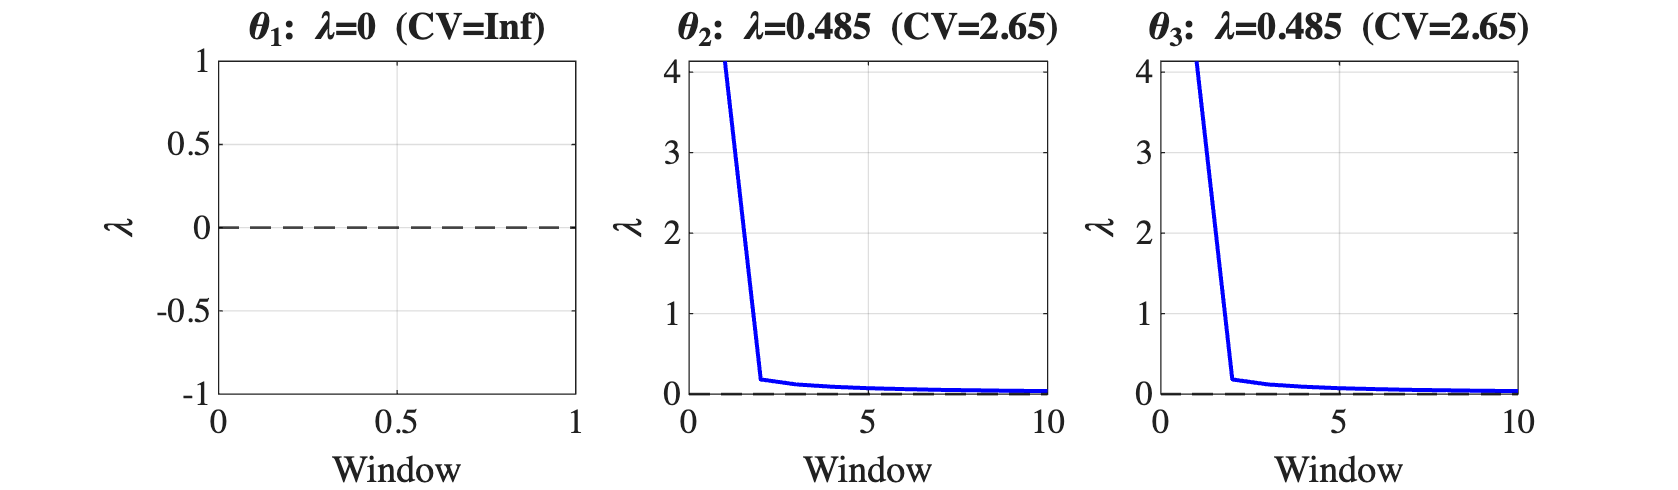

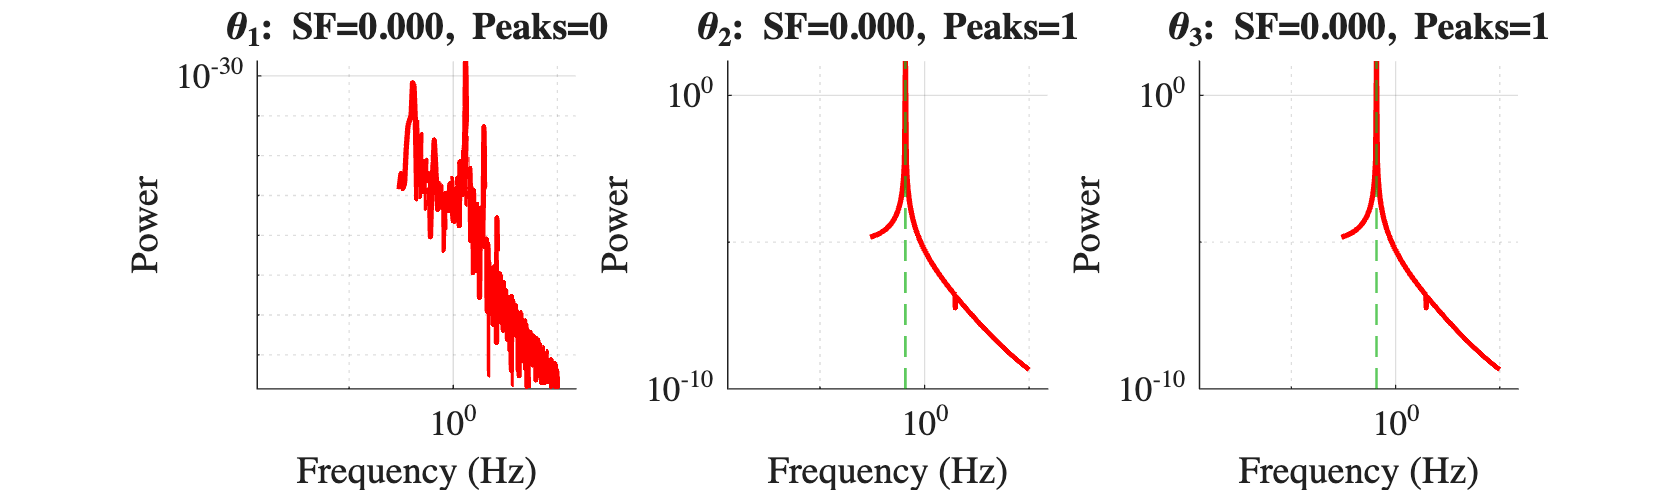

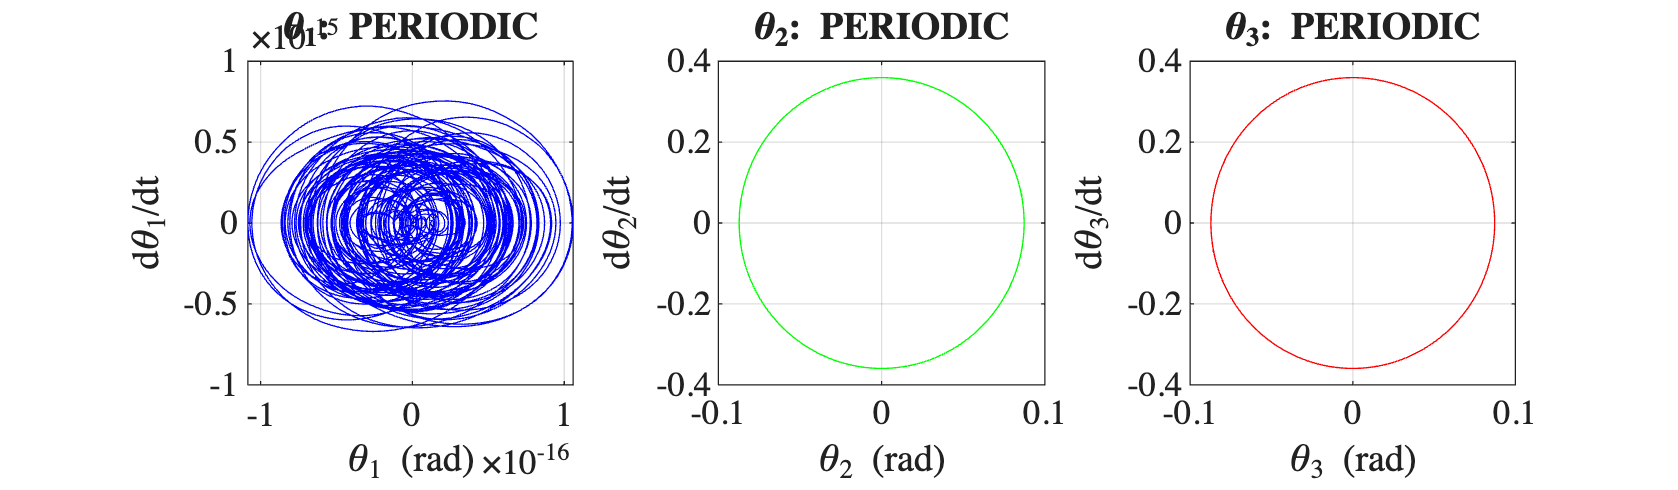

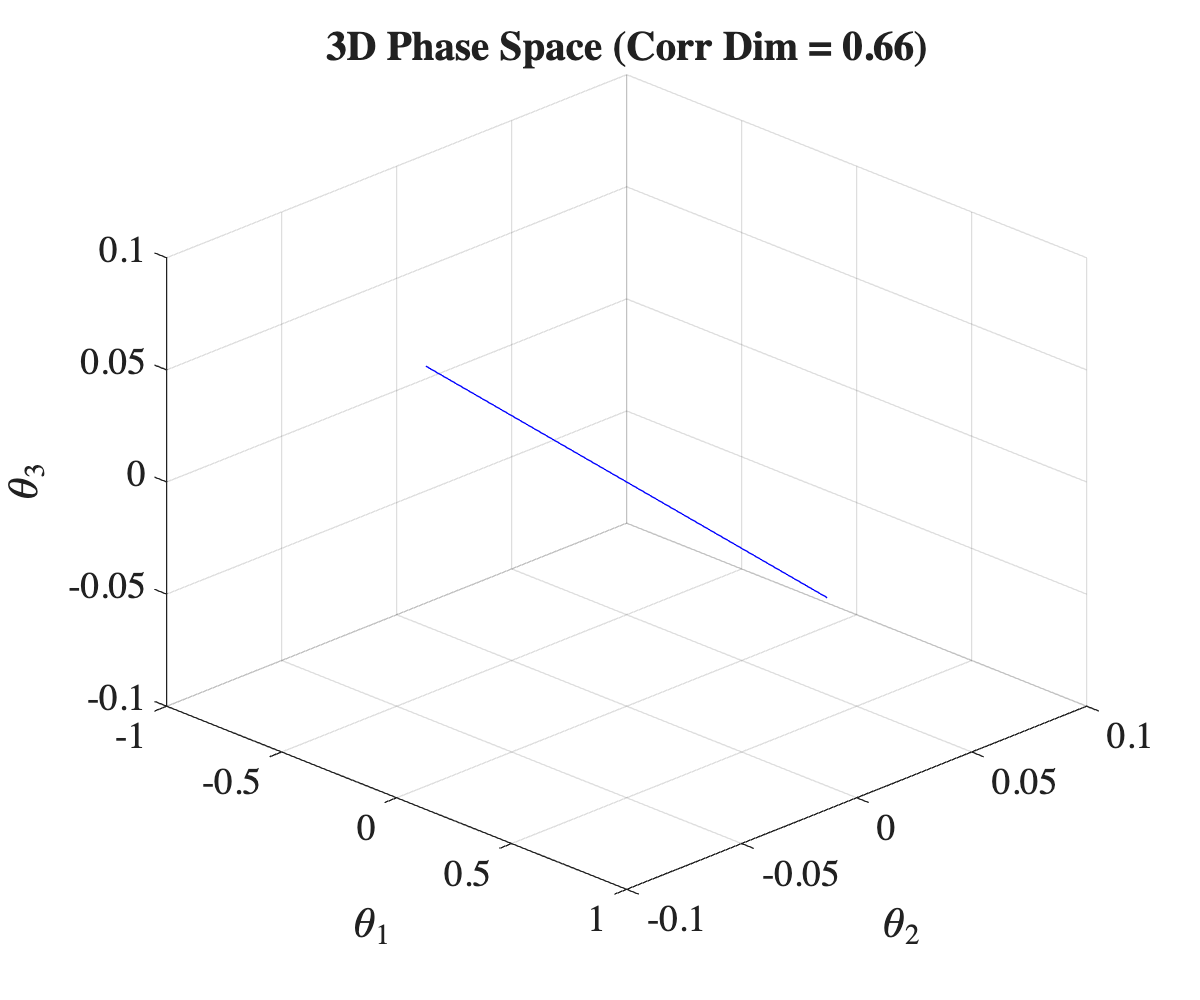

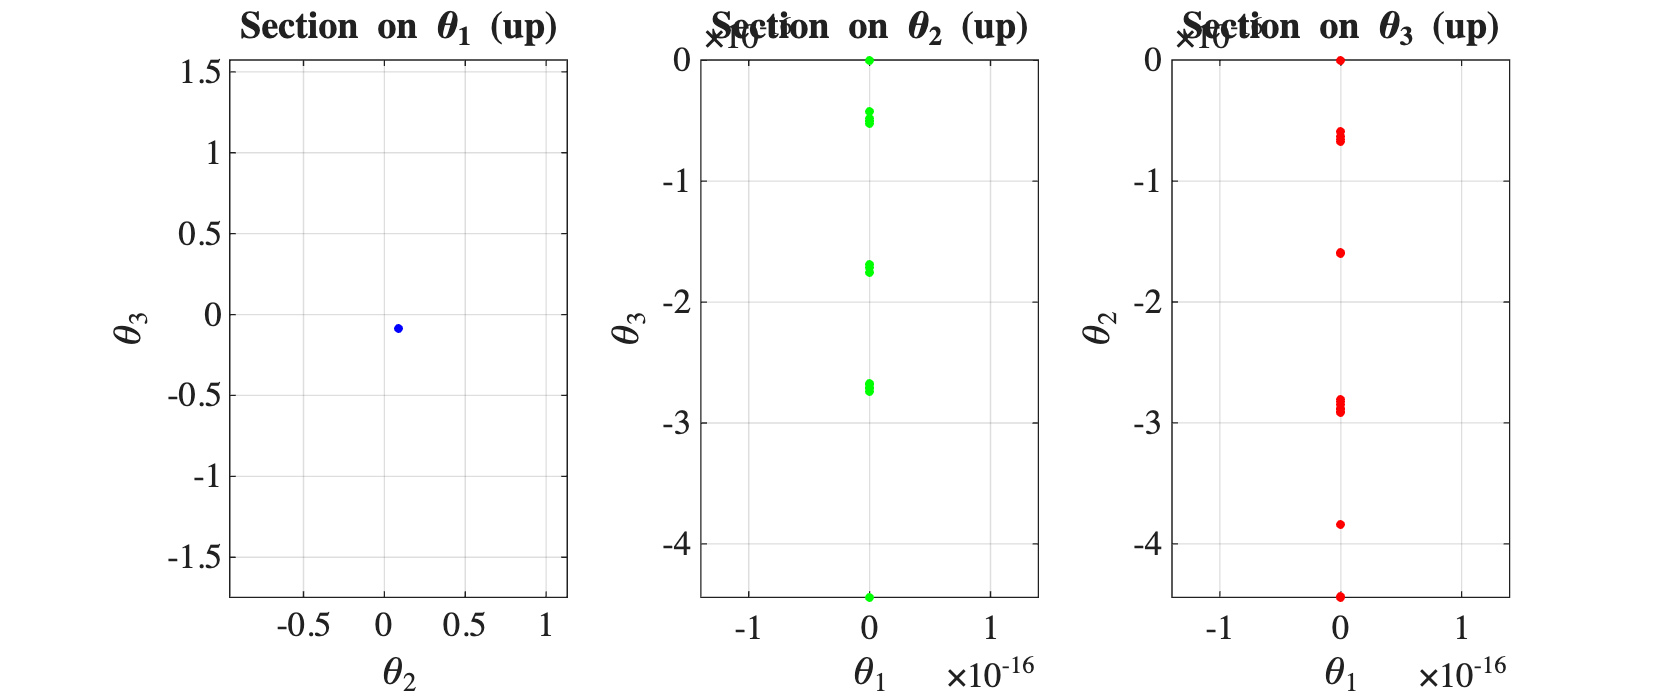

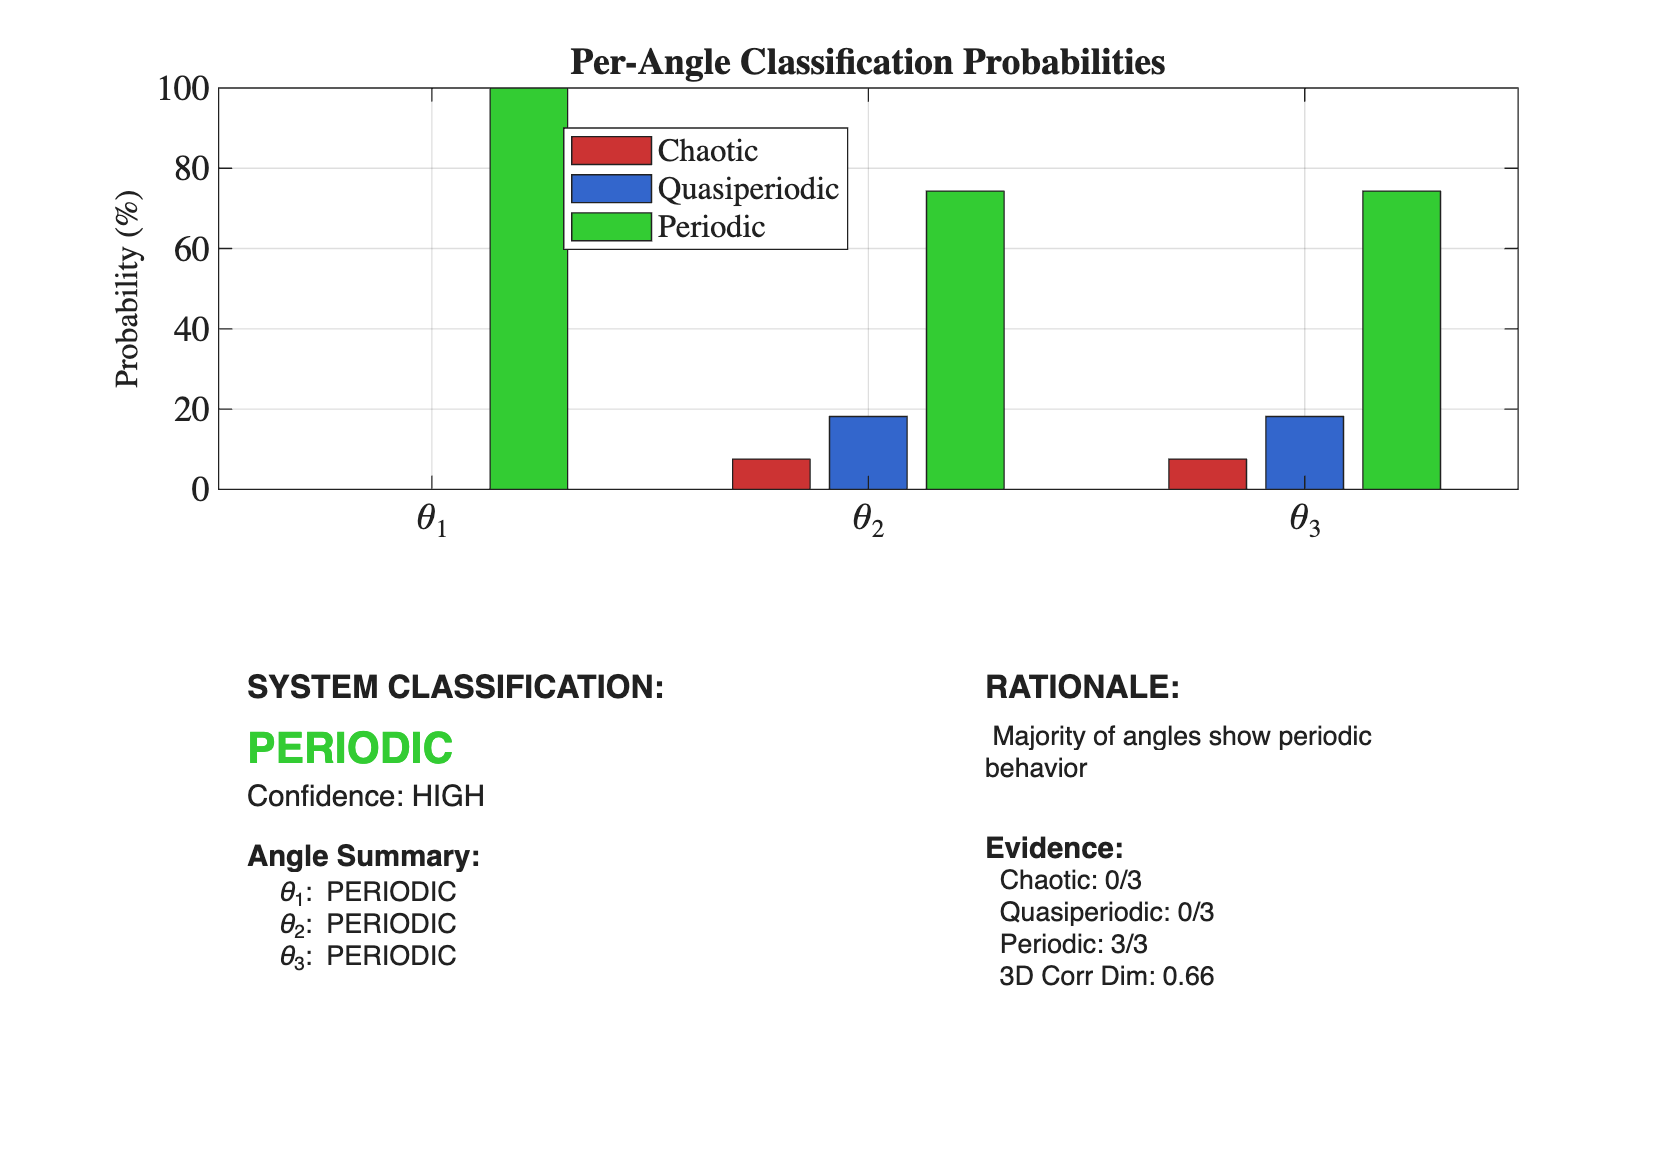


Created 6 diagnostic figures:
  1. Lyapunov Evolution (per angle)
  2. Power Spectra (per angle)
  3. Phase Portraits (per angle)
  4. 3D Phase Space
  5. Poincaré Sections
  6. System Classification Summary



create_per_angle_plots(theta1_wrapped, theta2_wrapped, theta3_wrapped, ...
                       theta1_unwrapped, theta2_unwrapped, theta3_unwrapped, ...
                       t, dt, results, angle_names, freq_min, freq_max);

fprintf('Diagnostics complete.\n');

Diagnostics complete.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%                               HELPER FUNCTIONS                          %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function y = wrapToPi_safe(x)
% wrapToPi_safe: wrap angles to [-pi, pi], toolbox-free
    y = mod(x + pi, 2*pi) - pi;
end

function [is_const, stats] = is_near_constant(x, dt)
% Detects signals that are "effectively constant" at machine precision.
% Uses adaptive thresholds based on eps and data scale.

    x = x(:);
    N = numel(x);
    if N < 8
        is_const = true;
        stats = struct('amp',0,'std',0,'vrms',0,'th_amp',0,'th_std',0,'th_vrms',0);
        return;
    end

    x_range = max(x) - min(x);
    x_std   = std(x);

    if nargin < 2 || isempty(dt) || dt<=0, dt = 1; end
    v     = gradient(x, dt);
    v_rms = sqrt(mean(v.^2));

    eps_scale = eps(max(1, max(abs(x))));
    th_amp  = max(1e-12, 1000*eps_scale);         % radians
    th_std  = max(1e-12,  300*eps_scale);
    th_vrms = max(1e-12/dt, 300*eps_scale/dt);    % rad/s

    is_const = (x_range <= th_amp) && (x_std <= th_std) && (v_rms <= th_vrms);
    stats = struct('amp',x_range,'std',x_std,'vrms',v_rms, ...
                   'th_amp',th_amp,'th_std',th_std,'th_vrms',th_vrms);
end

function [lambda, valid_pairs] = compute_lyapunov_1d(x, dt)
% Compute 1D Lyapunov exponent for a single time series (finite-time average)
    N = length(x);
    if N < 10, lambda = NaN; valid_pairs = 0; return; end

    % near-constant guard
    if std(x) <= max(1e-12, 300*eps(max(1, max(abs(x)))))
        lambda = NaN; valid_pairs = 0; return;
    end

    % Typical distance scale
    sample_size = min(100, N);
    sample_idx  = round(linspace(1, N, sample_size));
    sample_dists = pdist(x(sample_idx));
    if isempty(sample_dists) || all(isnan(sample_dists))
        lambda = NaN; valid_pairs = 0; return;
    end

    typical_dist      = median(sample_dists);
    max_neighbor_dist = max(1.0, typical_dist * 0.5);
    max_ratio         = 1000;

    distances  = zeros(N-1, 1);
    valid_count = 0;

    for i = 1:N-1
        state = x(i);
        next_state = x(i+1);

        % Find nearest neighbor (exclude temporal neighbors)
        dists = abs(x - state);
        dists(max(1,i-5):min(N,i+5)) = Inf;
        [min_dist, nn_idx] = min(dists);

        if ~isfinite(min_dist) || (min_dist > max_neighbor_dist) || (min_dist < 1e-12)
            continue;
        end

        if nn_idx < N
            d0 = abs(state      - x(nn_idx));
            d1 = abs(next_state - x(nn_idx+1));

            if d0 > 1e-12 && d1 > 1e-12 && d1/d0 < max_ratio
                distances(i) = log(d1/d0);
                valid_count = valid_count + 1;
            end
        end
    end

    distances = distances(distances ~= 0);
    if ~isempty(distances) && valid_count > 5
        lambda = mean(distances) / dt;
        valid_pairs = valid_count;
    else
        lambda = NaN;
        valid_pairs = valid_count;
    end
end

function K = compute_01_test(x)
% Robust 0–1 test: normalize; use multiple c-values and take median K
    x = x(:);
    x = x - mean(x);
    sx = std(x);
    if sx <= max(1e-12, 300*eps(max(1, max(abs(x)))))
        K = 0; return;   % treat flat as non-chaotic
    end
    x = x / sx;

    N = length(x);
    cs = [pi/5, pi/sqrt(7), pi*(sqrt(5)-1)/2];
    Ks = zeros(1, numel(cs));

    for j = 1:numel(cs)
        c = cs(j);
        p = zeros(N,1);
        for n = 2:N
            p(n) = p(n-1) + x(n) * cos(c * n);
        end
        M = zeros(floor(N/10),1);
        for n = 1:numel(M)
            M(n) = mean((p(n+1:end) - p(1:end-n)).^2);
        end
        Ks(j) = corr((1:numel(M))', M);
    end
    K = median(Ks);
end

function D = compute_correlation_dimension(X)
% Grassberger–Procaccia-style slope estimate on C(r) vs r
    N = min(size(X, 1), 1000);
    X = X(1:N, :);

    r_vals = logspace(-2, 0, 20);
    C = zeros(size(r_vals));

    d = pdist(X);
    for i = 1:length(r_vals)
        r = r_vals(i);
        C(i) = sum(d < r) / numel(d);
    end

    log_r = log(r_vals);
    log_C = log(C + eps);

    idx_start = floor(0.2 * length(log_r));
    idx_end   = floor(0.8 * length(log_r));

    p = polyfit(log_r(idx_start:idx_end), log_C(idx_start:idx_end), 1);
    D = p(1);
end

function [freq, power] = compute_power_spectrum(x, dt)
% Simple periodogram (one-sided)
    N = length(x);
    Y = fft(x - mean(x));
    P = abs(Y).^2 / N;
    freq  = (0:N-1) / (N*dt);
    half  = 1:floor(N/2);
    freq  = freq(half);
    power = P(half);
end

function SF = compute_spectral_flatness(power)
% Geometric mean / arithmetic mean with power flooring
    p = power(:);
    if isempty(p) || all(p <= 0)
        SF = 0; return;
    end
    p_floor = max(1e-24, 100*eps(max(p)));
    p = max(p, p_floor);
    geometric_mean  = exp(mean(log(p)));
    arithmetic_mean = mean(p);
    SF = geometric_mean / arithmetic_mean;
end

function points = extract_poincare_interp(theta_sec, theta_x, theta_y, t, direction, method)
% Poincaré sampler with sub-sample interpolation at zero-crossings of theta_sec.
% direction = +1 (up), -1 (down), 0 (both)
% method: 'linear' or 'cubic' (Hermite)

    if nargin < 5 || isempty(direction), direction = +1; end
    if nargin < 6 || isempty(method),    method    = 'linear'; end

    theta_sec = theta_sec(:);
    theta_x   = theta_x(:);
    theta_y   = theta_y(:);
    N = numel(theta_sec);

    if ~(numel(theta_x)==N && numel(theta_y)==N)
        error('extract_poincare_interp: inputs must have same length.');
    end
    if isempty(t)
        t = (1:N)';   % assume unit sampling
    else
        t = t(:);
        if numel(t) ~= N
            error('extract_poincare_interp: t must match data length.');
        end
    end

    s1  = sign(theta_sec); s1(s1==0) = 1;
    idx = find(s1(1:end-1).*s1(2:end) < 0);
    if isempty(idx)
        points = [theta_x(1), theta_y(1)];
        return;
    end

    if strcmp(method,'cubic')
        dth = local_derivative(theta_sec, t);
        dx  = local_derivative(theta_x,   t);
        dy  = local_derivative(theta_y,   t);
    end

    out = zeros(0,2);
    for k = 1:numel(idx)
        i = idx(k);
        ti = t(i); tip1 = t(i+1);
        h  = tip1 - ti; if h <= 0, continue; end

        th_i  = theta_sec(i);
        th_ip = theta_sec(i+1);

        seg_slope = (th_ip - th_i)/h;
        if direction==+1 && seg_slope <= 0, continue; end
        if direction==-1 && seg_slope >= 0, continue; end

        switch method
            case 'linear'
                denom = (th_i - th_ip);
                if abs(denom) < eps, continue; end
                s = th_i / (th_i - th_ip);
                if ~(s>=-1e-9 && s<=1+1e-9), continue; end
                s = min(max(s,0),1);

            case 'cubic'
                si = th_i; sip = th_ip;
                mi = dth(i)*h; mp = dth(i+1)*h;
                H = @(z) (2*z.^3-3*z.^2+1).*si + (z.^3-2*z.^2+z).*mi + ...
                         (-2*z.^3+3*z.^2).*sip + (z.^3-z.^2).*mp;
                try
                    s = fzero(@(z) H(z), [0,1]);
                catch
                    denom = (th_i - th_ip);
                    if abs(denom) < eps, continue; end
                    s = th_i / (th_i - th_ip);
                    if ~(s>=-1e-9 && s<=1+1e-9), continue; end
                    s = min(max(s,0),1);
                end
        end

        % Interpolate theta_x, theta_y at s
        switch method
            case 'linear'
                xi = theta_x(i);  xip = theta_x(i+1);
                yi = theta_y(i);  yip = theta_y(i+1);
                x_cross = (1-s)*xi + s*xip;
                y_cross = (1-s)*yi + s*yip;

            case 'cubic'
                xi = theta_x(i);  xip = theta_x(i+1);
                yi = theta_y(i);  yip = theta_y(i+1);
                mix = dx(i)*h;    mxp = dx(i+1)*h;
                miy = dy(i)*h;    myp = dy(i+1)*h;
                x_cross = hermite_eval(xi, xip, mix, mxp, s);
                y_cross = hermite_eval(yi, yip, miy, myp, s);
        end

        out(end+1, :) = [x_cross, y_cross]; %#ok<AGROW>
    end

    if isempty(out)
        points = [theta_x(1), theta_y(1)];
    else
        points = out;
    end
end

function d = local_derivative(y, t)
% Derivative for uniform or mildly non-uniform samples
    N = numel(y); d = zeros(N,1);
    if all(diff(t)>0) && max(abs(diff(diff(t)))) < 1e-12*max(diff(t))
        dt = mean(diff(t));
        d  = gradient(y, dt);
    else
        d(1) = (y(2)-y(1))/(t(2)-t(1));
        d(N) = (y(N)-y(N-1))/(t(N)-t(N-1));
        for i = 2:N-1
            dti  = t(i)   - t(i-1);
            dtip = t(i+1) - t(i);
            d(i) = ( (y(i+1)-y(i))/dtip * dti + (y(i)-y(i-1))/dti * dtip ) / (dti+dtip);
        end
    end
end

function H = hermite_eval(y0, y1, m0, m1, s)
% Cubic Hermite interpolation on [0,1]
    H = (2*s.^3 - 3*s.^2 + 1).*y0 + (s.^3 - 2*s.^2 + s).*m0 ...
      + (-2*s.^3 + 3*s.^2).*y1 + (s.^3 - s.^2).*m1;
end

function [class, probs] = classify_lle(lambda)
% Heuristic mapping from LLE to class probabilities
    if ~isfinite(lambda)
        class = 'PERIODIC'; probs = [0.05, 0.15, 0.8]; return;
    end
    if lambda > 0.01
        class = 'CHAOTIC';       probs = [0.9,  0.08, 0.02];
    elseif lambda > -0.001
        class = 'QUASIPERIODIC'; probs = [0.3,  0.6,  0.1 ];
    else
        class = 'PERIODIC';      probs = [0.05, 0.15, 0.8 ];
    end
end

function [class, probs] = classify_01test(K)
% Heuristic mapping from 0–1 K-statistic to class probabilities
    if ~isfinite(K), K = 0; end
    if K > 0.7
        class = 'CHAOTIC';       probs = [0.85, 0.10, 0.05];
    elseif K > 0.3
        class = 'QUASIPERIODIC'; probs = [0.20, 0.60, 0.20];
    else
        class = 'PERIODIC';      probs = [0.05, 0.15, 0.80];
    end
end

function [class, probs] = classify_corrdim(D)
% Heuristic mapping from correlation dimension to class probabilities
    if ~isfinite(D), D = 0; end
    if D > 2.5
        class = 'CHAOTIC';       probs = [0.80, 0.15, 0.05];
    elseif D > 1.5
        class = 'QUASIPERIODIC'; probs = [0.15, 0.70, 0.15];
    else
        class = 'PERIODIC';      probs = [0.05, 0.15, 0.80];
    end
end

function [class, probs] = classify_spectrum(SF)
% Heuristic mapping from spectral flatness to class probabilities
    if ~isfinite(SF), SF = 0; end
    if SF > 0.5
        class = 'CHAOTIC';       probs = [0.75, 0.20, 0.05];
    elseif SF > 0.2
        class = 'QUASIPERIODIC'; probs = [0.20, 0.60, 0.20];
    else
        class = 'PERIODIC';      probs = [0.05, 0.20, 0.75];
    end
end

function [class, probs] = classify_peaks(n_peaks)
% Heuristic mapping from number of peaks to class probabilities
    if ~isfinite(n_peaks), n_peaks = 0; end
    if n_peaks > 20
        class = 'CHAOTIC';       probs = [0.70, 0.25, 0.05];
    elseif n_peaks > 5
        class = 'QUASIPERIODIC'; probs = [0.15, 0.70, 0.15];
    else
        class = 'PERIODIC';      probs = [0.05, 0.20, 0.75];
    end
end

function create_per_angle_plots(theta1_w, theta2_w, theta3_w, ...
                                theta1_u, theta2_u, theta3_u, ...
                                t, dt, results, angle_names, freq_min, freq_max)
% Visualization dashboard

    % Figure 1: Per-angle Lyapunov evolution
    figure('Position', [50, 600, 1200, 350], 'Name', 'Lyapunov Evolution');
    for i = 1:3
        subplot(1, 3, i);
        lambda_windows = results.angle_results(i).lambda_windows;
        plot(lambda_windows, 'b-', 'LineWidth', 1.5);
        hold on;
        if results.angle_results(i).lambda_reliable
            lambda_max = results.angle_results(i).lambda_max;
            lambda_std = results.angle_results(i).lambda_std;
            yline(lambda_max, 'r--', 'Mean', 'LineWidth', 2);
            yline(lambda_max + lambda_std, 'r:', 'LineWidth', 1);
            yline(lambda_max - lambda_std, 'r:', 'LineWidth', 1);
        end
        yline(0, 'k--', 'LineWidth', 1);
        hold off;
        xlabel('Window', 'FontSize', 11);
        ylabel('\lambda', 'FontSize', 11);
        title(sprintf('%s: \\lambda=%.3g (CV=%.2f)', angle_names{i}, ...
            results.angle_results(i).lambda_max, results.angle_results(i).lambda_cv));
        grid on;
    end

    % Figure 2: Per-angle power spectra
    figure('Position', [50, 200, 1200, 350], 'Name', 'Power Spectra');
    for i = 1:3
        subplot(1, 3, i);
        freq  = results.angle_results(i).freq;
        power = results.angle_results(i).power;

        xscale('log'); yscale('log'); hold on;
        freq_mask = (freq >= freq_min) & (freq <= freq_max);
        if any(freq_mask)
            plot(freq(freq_mask), power(freq_mask), 'r-', 'LineWidth', 2);
        end

        % draw vertical lines at detected peak frequencies
        peak_freqs = results.angle_results(i).peak_frequencies;
        if ~isempty(peak_freqs)
            for pf = peak_freqs(:)'
                xline(pf, 'Color', [0.1 0.7 0.1], 'LineStyle', '--', 'LineWidth', 1.0);
            end
        end
        hold off;

        xlabel('Frequency (Hz)', 'FontSize', 11);
        ylabel('Power', 'FontSize', 11);
        title(sprintf('%s: SF=%.3f, Peaks=%d', angle_names{i}, ...
            results.angle_results(i).spectral_flatness, results.angle_results(i).num_peaks));
        grid on;
        %xlim([max(eps, min(freq(freq>0), 1e-3)), min(freq_max*1.5, max(freq))]);
        % --- Robust x-limits for log-x plot ---
fpos = freq(freq > 0 & isfinite(freq));                 % positive, finite freqs
lo   = max(1e-3, min(fpos, [], 'omitnan'));             % lower > 0
hi   = min(freq_max*1.5, max(freq, [], 'omitnan'));     % upper cap

% Fallbacks if data are degenerate or hi<=lo
if isempty(fpos) || ~isfinite(lo) || ~isfinite(hi) || hi <= lo
    lo = 1e-3;
    hi = max(10*lo, freq_max);                          % ensure hi>lo
end

xlim([lo, hi]);

    end

    % Figure 3: Phase portraits
    omega1 = gradient(theta1_u, dt);
    omega2 = gradient(theta2_u, dt);
    omega3 = gradient(theta3_u, dt);

    figure('Position', [50, -200, 1200, 350], 'Name', 'Phase Portraits');
    subplot(1, 3, 1);
    plot(theta1_u, omega1, 'b-', 'LineWidth', 0.5);
    xlabel(sprintf('%s (rad)', angle_names{1}), 'FontSize', 11);
    ylabel(sprintf('d%s/dt', angle_names{1}), 'FontSize', 11);
    title(sprintf('%s: %s', angle_names{1}, results.angle_results(1).motion_type));
    grid on;

    subplot(1, 3, 2);
    plot(theta2_u, omega2, 'g-', 'LineWidth', 0.5);
    xlabel(sprintf('%s (rad)', angle_names{2}), 'FontSize', 11);
    ylabel(sprintf('d%s/dt', angle_names{2}), 'FontSize', 11);
    title(sprintf('%s: %s', angle_names{2}, results.angle_results(2).motion_type));
    grid on;

    subplot(1, 3, 3);
    plot(theta3_u, omega3, 'r-', 'LineWidth', 0.5);
    xlabel(sprintf('%s (rad)', angle_names{3}), 'FontSize', 11);
    ylabel(sprintf('d%s/dt', angle_names{3}), 'FontSize', 11);
    title(sprintf('%s: %s', angle_names{3}, results.angle_results(3).motion_type));
    grid on;

    % Figure 4: 3D Phase space
    figure('Position', [50, -600, 600, 500], 'Name', '3D Phase Space');
    plot3(theta1_w, theta2_w, theta3_w, 'b-', 'LineWidth', 0.5);
    xlabel(sprintf('%s', angle_names{1}), 'FontSize', 12);
    ylabel(sprintf('%s', angle_names{2}), 'FontSize', 12);
    zlabel(sprintf('%s', angle_names{3}), 'FontSize', 12);
    title(sprintf('3D Phase Space (Corr Dim = %.2f)', results.correlation_dim), 'FontSize', 14);
    grid on; view(45, 30);

    % Figure 5: Poincaré sections (three combinations)
    figure('Position', [700, -600, 1200, 500], 'Name', 'Poincaré Sections');

    % Section on theta1 (upward crossing): plot (theta2 vs theta3)
    pts_1 = extract_poincare_set(theta1_w, theta2_w, theta3_w, t, +1);
    subplot(1,3,1);
    plot(pts_1(:,1), pts_1(:,2), 'b.', 'MarkerSize', 10);
    xlabel(angle_names{2}, 'FontSize', 12);  % θ2
    ylabel(angle_names{3}, 'FontSize', 12);  % θ3
    title('Section \theta_1', 'FontSize', 12); grid on; axis equal;

    % Section on theta2 (upward crossing): plot (theta1 vs theta3)
    pts_2 = extract_poincare_set(theta2_w, theta1_w, theta3_w, t, +1);
    subplot(1,3,2);
    plot(pts_2(:,1), pts_2(:,2), 'g.', 'MarkerSize', 10);
    xlabel(angle_names{1}, 'FontSize', 12);  % θ1
    ylabel(angle_names{3}, 'FontSize', 12);  % θ3
    title('Section \theta_2', 'FontSize', 12); grid on; axis equal;

    % Section on theta3 (upward crossing): plot (theta1 vs theta2)
    pts_3 = extract_poincare_set(theta3_w, theta1_w, theta2_w, t, +1);
    subplot(1,3,3);
    plot(pts_3(:,1), pts_3(:,2), 'r.', 'MarkerSize', 10);
    xlabel(angle_names{1}, 'FontSize', 12);  % θ1
    ylabel(angle_names{2}, 'FontSize', 12);  % θ2
    title('Section \theta_3', 'FontSize', 12); grid on; axis equal;

    % Figure 6: Summary dashboard
    figure('Position', [100, 100, 1000, 700], 'Name', 'System Classification Summary');

    % Top: Per-angle probabilities
    subplot(2, 2, [1 2]);
    angle_probs = zeros(3, 3);
    for i = 1:3
        angle_probs(i, :) = results.angle_results(i).probabilities;
    end
    b = bar(angle_probs * 100, 'grouped');
    b(1).FaceColor = [0.8 0.2 0.2];  % Chaotic - red
    b(2).FaceColor = [0.2 0.4 0.8];  % Quasiperiodic - blue
    b(3).FaceColor = [0.2 0.8 0.2];  % Periodic - green
    xticklabels(angle_names);
    ylabel('Probability (%)', 'FontSize', 12);
    title('Per-Angle Classification Probabilities', 'FontSize', 14, 'FontWeight', 'bold');
    legend('Chaotic', 'Quasiperiodic', 'Periodic', 'Location', 'best');
    grid on; ylim([0, 100]);

    % Bottom left: System classification
    subplot(2, 2, 3);
    axis([0 1 0 1]); axis off;
    if strcmp(results.system_classification, 'CHAOTIC')
        type_color = [0.8 0.2 0.2];
    elseif strcmp(results.system_classification, 'QUASIPERIODIC')
        type_color = [0.2 0.4 0.8];
    else
        type_color = [0.2 0.8 0.2];
    end
    y = 0.9;
    text(0.05, y, 'SYSTEM CLASSIFICATION:', 'FontSize', 12, 'FontWeight', 'bold'); y = y - 0.15;
    text(0.05, y, results.system_classification, 'FontSize', 16, 'FontWeight', 'bold', 'Color', type_color); y = y - 0.12;
    text(0.05, y, sprintf('Confidence: %s', results.system_confidence), 'FontSize', 11); y = y - 0.15;

    text(0.05, y, 'Angle Summary:', 'FontSize', 11, 'FontWeight', 'bold'); y = y - 0.1;
    for i = 1:3
        text(0.05, y, sprintf('  %s: %s', angle_names{i}, results.angle_results(i).motion_type), 'FontSize', 10);
        y = y - 0.08;
    end

    % Bottom right: Rationale
    subplot(2, 2, 4);
    axis([0 1 0 1]); axis off;
    y = 0.9;
    text(0.05, y, 'RATIONALE:', 'FontSize', 12, 'FontWeight', 'bold'); y = y - 0.12;

    % Word wrap the rationale
    words = strsplit(results.system_rationale); line = '';
    for i = 1:length(words)
        test_line = [line, ' ', words{i}];
        if length(test_line) > 40 && ~isempty(line)
            text(0.05, y, line, 'FontSize', 10); y = y - 0.08; line = words{i};
        else
            line = test_line;
        end
    end
    if ~isempty(line)
        text(0.05, y, line, 'FontSize', 10); y = y - 0.12;
    end

    y = y - 0.08;
    text(0.05, y, 'Evidence:', 'FontSize', 11, 'FontWeight', 'bold'); y = y - 0.08;
    text(0.05, y, sprintf('  Chaotic: %d/3', results.num_chaotic), 'FontSize', 10); y = y - 0.08;
    text(0.05, y, sprintf('  Quasiperiodic: %d/3', results.num_quasiperiodic), 'FontSize', 10); y = y - 0.08;
    text(0.05, y, sprintf('  Periodic: %d/3', results.num_periodic), 'FontSize', 10); y = y - 0.08;
    text(0.05, y, sprintf('  3D Corr Dim: %.2f', results.correlation_dim), 'FontSize', 10);

    fprintf('\nCreated 6 diagnostic figures:\n');
    fprintf('  1. Lyapunov Evolution (per angle)\n');
    fprintf('  2. Power Spectra (per angle)\n');
    fprintf('  3. Phase Portraits (per angle)\n');
    fprintf('  4. 3D Phase Space\n');
    fprintf('  5. Poincaré Sections\n');
    fprintf('  6. System Classification Summary\n\n');
end

function pts = extract_poincare_set(theta_sec, theta_x, theta_y, t, direction)
% Convenience wrapper to call the interpolating sampler
    if nargin < 5, direction = +1; end
    pts = extract_poincare_interp(theta_sec, theta_x, theta_y, t, direction, 'linear');
end